close all;
clear variables;

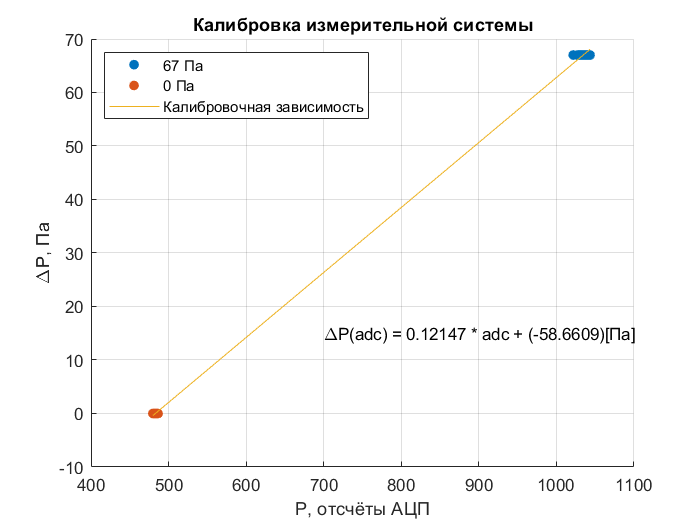

% Калибровка

calib = importdata("C:\Users\hp\Desktop\Измерение расхода затопленной струи\2-experimentData\calib.dat");
calibzero = importdata("C:\Users\hp\Desktop\Измерение расхода затопленной струи\2-experimentData\calibzero.dat");

pas67 = ones(length(calib), 1)*67;
pas0 = zeros(length(calibzero), 1);

cAdc = [calib(:,2); calibzero(:,2)];
cPas = [pas67, pas0];

c = polyfit(cAdc, cPas, 1);

calibrF = figure();
hold all;

plot(calib(:,2), pas67, '.', 'MarkerSize', 20);
plot(calibzero(:,2), pas0, '.', 'MarkerSize', 20);
plot(cAdc, polyval(c, cAdc));

legend('67 Па', '0 Па', 'Калибровочная зависимость', 'Location', 'NorthWest');

grid on;
xlabel('P, отсчёты АЦП');
ylabel('\DeltaP, Па');
title('Калибровка измерительной системы');
text(700, 15, ['\DeltaP(adc) = ', num2str(c(1)), ' * adc + (', num2str(c(2)), ')', '[Па]']);

saveas(calibrF, "C:\Users\hp\Desktop\Измерение расхода затопленной струи\calibration.png");

% Загрузка данных

mm01 = load("C:\Users\hp\Desktop\Измерение расхода затопленной струи\2-experimentData\01mm.dat");
mm11 = load("C:\Users\hp\Desktop\Измерение расхода затопленной струи\2-experimentData\11mm.dat");
mm21 = load("C:\Users\hp\Desktop\Измерение расхода затопленной струи\2-experimentData\21mm.dat");
mm31 = load("C:\Users\hp\Desktop\Измерение расхода затопленной струи\2-experimentData\31mm.dat");
mm41 = load("C:\Users\hp\Desktop\Измерение расхода затопленной струи\2-experimentData\41mm.dat");
mm51 = load("C:\Users\hp\Desktop\Измерение расхода затопленной струи\2-experimentData\51mm.dat");
mm61 = load("C:\Users\hp\Desktop\Измерение расхода затопленной струи\2-experimentData\61mm.dat");
mm71 = load("C:\Users\hp\Desktop\Измерение расхода затопленной струи\2-experimentData\71mm.dat");

dx = 0.25;
x = mm01(:,1)' * 0.25;

p01 = polyval(c, mm01(:,2));
p11 = polyval(c, mm11(:,2));
p21 = polyval(c, mm21(:,2));
p31 = polyval(c, mm31(:,2));
p41 = polyval(c, mm41(:,2));
p51 = polyval(c, mm51(:,2));
p61 = polyval(c, mm61(:,2));
p71 = polyval(c, mm71(:,2));

pressure = [p01, p11, p21, p31, p41, p51, p61, p71];
zNames = {'1 мм'; '11 мм'; '21 мм'; '31 мм'; '41 мм'; '51 мм'; '61 мм'; '71 мм'};
z = [1, 11, 21, 31, 41, 51, 61, 71];

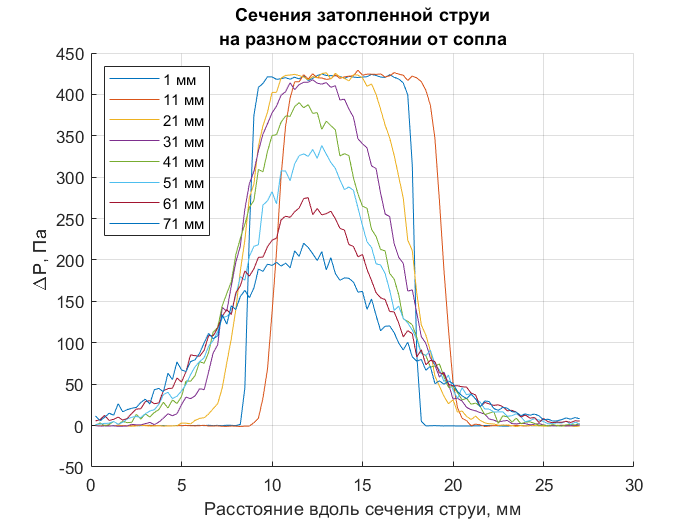

% График изменения давления вдоль сечении струи на разных расстояниях от сопла

dataF = figure();
hold on;

for i = 1:size(pressure, 2)
    plot(x, pressure(:, i), 'DisplayName', zNames{i});
end

grid on;
title({'Сечения затопленной струи', 'на разном расстоянии от сопла'});
xlabel('Расстояние вдоль сечения струи, мм');
ylabel('\DeltaP, Па');

legend('Location', 'NorthWest');
saveas(dataF, "C:\Users\hp\Desktop\Измерение расхода затопленной струи\pressure.png" )

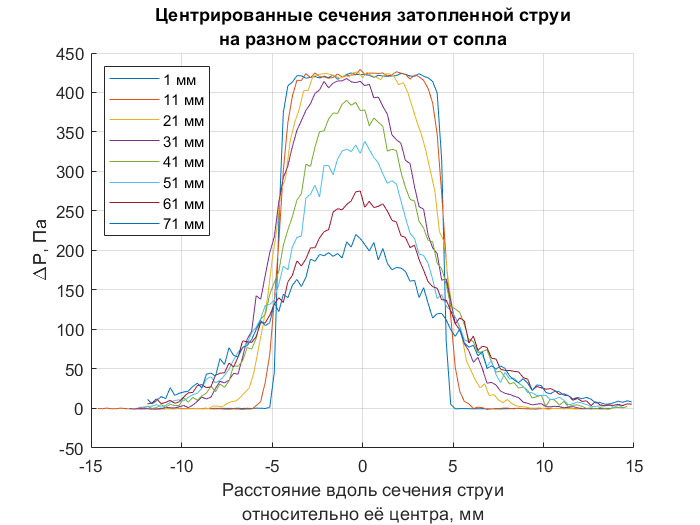

% Центрирование

centerF = figure();
hold on;

xCent = zeros(size(pressure));
offset = 50;

for i = 1:size(pressure,2)
    right = x(find(pressure(:,i) > offset, 1, 'last'));
    left = x(find(pressure(:, i) > offset, 1));
    center = (left + right)/2;
    xCent(:, i) = x - center;
    
    plot(xCent(:, i), pressure(:, i), 'DisplayName', zNames{i});
end

grid on;
title({'Центрированные сечения затопленной струи', 'на разном расстоянии от сопла'});
xlabel({'Расстояние вдоль сечения струи', 'относительно её центра, мм'});
ylabel('\DeltaP, Па');
legend('Location', 'NorthWest');
saveas(centerF, "C:\Users\hp\Desktop\Измерение расхода затопленной струи\centered.png" )

% Рассчет скоростей

speed = zeros(2, size(pressure, 1), 8);

for i = 1:8
    for j = 1:size(xCent)
        speed(1, j, i) = xCent(j, i);
        speed(2, j, i) = sqrt((2*(pressure(j, i)-c(2))/1.2));
    end
end

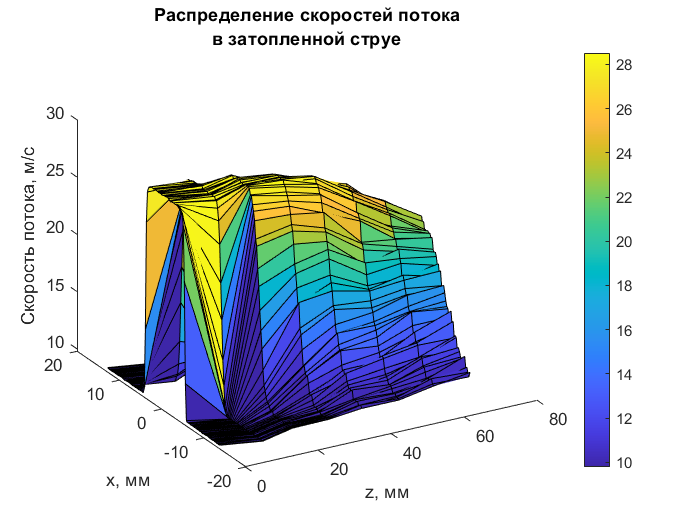

% График значений скоростей для разных расстояний от сопла

surfF = figure();

hold on;

Z = zeros(8, 108);
for i = 1:8
    for j = 1:108
        Z(i, j)= z(1, i);
    end
end

Y = zeros(8, 108);
for i = 1:8
    for j = 1:108
        Y(i, j) = speed(2,j,i);
    end
end
surf(xCent',Z,Y);
set(gca, {'YDir'}, {'reverse'})
colorbar;
view(-120, 30)
title({'Распределение скоростей потока', 'в затопленной струе'})
xlabel('x, мм');
ylabel('z, мм');
zlabel('Скорость потока, м/с');

saveas(surfF, "C:\Users\hp\Desktop\Измерение расхода затопленной струи\surface.png" )

% Расход струи